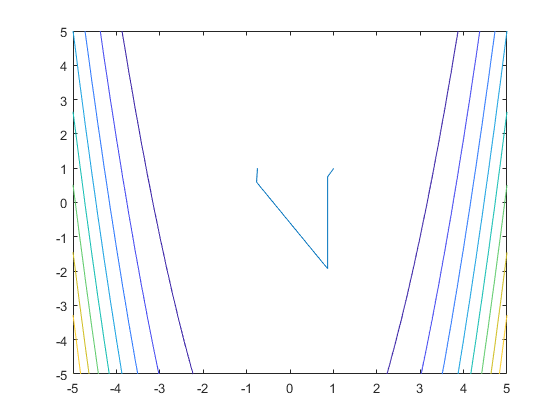

% Copyright: Theocharis Karathymios (github name: karatgit)
% Minimization of the function f using the Newton method
% Define the objective function
syms x y
f(x,y) = 100*(y-x.^2).^2 + (1-x).^2;
% Calculate gradients of f
grad_f(x,y) = gradient(f);
grad2f(x,y) = hessian(f);
% Set initial point and search range
x_k = -3/4;
y_k = 1;
epsilon = 0.001;
% Calculate grad2f(xk)
grad2f_xk = double(grad2f(x_k,y_k));
grad2f_xk_inv = inv(grad2f_xk);
% Calculate f(xk)
f_xk = double(f(x_k,y_k));
% Calculate gradf(xk)
gradf_xk = double(grad_f(x_k,y_k));
% Set s and starting vectors for x and y
s = -grad2f_xk_inv*gradf_xk;
X = x_k;
Y = y_k;
J = log((x_k-1)^2+(y_k-1)^2);
% Newton's Algorithm
%_________________________________
while norm(gradf_xk)>epsilon
    x_k = x_k + s(1,1);
    y_k = y_k + s(2,1);
    J_new = log((x_k-1)^2+(y_k-1)^2);
    gradf_xk = double(grad_f(x_k,y_k));
    grad2f_xk = double(grad2f(x_k,y_k));
    grad2f_xk_inv = inv(grad2f_xk);
    X = [X x_k];
    Y = [Y y_k];
    J = [J J_new];
    s = -grad2f_xk_inv*gradf_xk;
end
optimal_point = [x_k;y_k];
% Plot f level sets and journey of (x,y)
fcontour(f);
hold on;
plot(X,Y);
hold off;

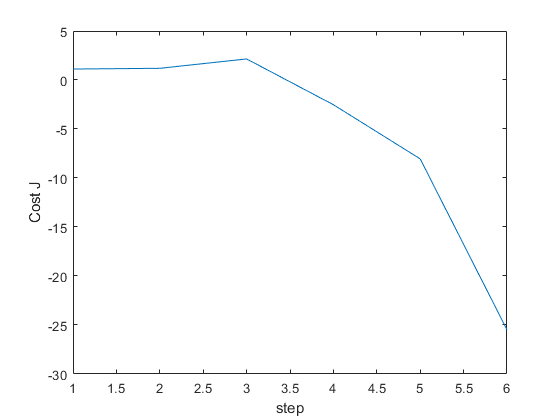

plot(J);
ylabel('Cost J');
xlabel('step');